% DISCLAIMER
% Installed Symbolic Math Toolbox to gain access to diff() function for derivatives
e = 10.^-4

e = 1.0000e-04

x0 = 5

x0 = 5

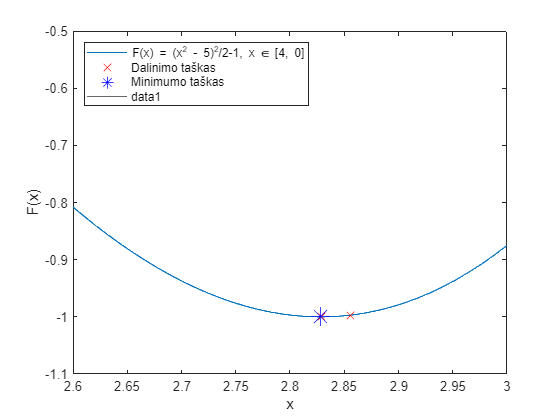

 
[debugArray, cutCount, y] = newton_div(e, x0);
x = 0:0.001:5;
f = givenFunction(x);

plot(x, f);
hold on;
plot(debugArray(:, 1), debugArray(:, 2), "xr", 'MarkerSize', 8);
plot(debugArray(end, 1), debugArray(end, 2), 'b*', 'MarkerSize', 14);
legend(["F(x) = (x^2 - 5)^2/2-1, x ∈ [4, 0]", "Dalinimo taškas", "Minimumo taškas"], "location","northwest");
ylim([-1.1 -0.5])
xlim([2.6 3])
yline(0)
ylabel("F(x)")
xlabel("x")
grid off
hold off;


disp("Loops: " + cutCount + ";")

Loops: 5;


disp("Main function called: " + length(debugArray) + " times.")

Main function called: 6 times.


disp("Last f(x) value: " + debugArray(length(debugArray), 2))

Last f(x) value: -1


a = 8;
    b = 8;
    syms x real
    f = (x.^2 - a).^2 /b - 1;
    ff = diff(f);
    ff = x/2 .* (x.^2 - a);
    fff = diff(ff)

%givenFunction = @(x) (x.^2 - a).^2 /b -1
function [f, ff, fff] = givenFunction(x)
    a = 8;
    b = 8;
    %syms x real
    f = (x.^2 - a).^2 /b - 1;
    %ff = diff(f);
    ff = x/2 .* (x.^2 - a);
    %fff = diff(ff)
    fff = (3/2) * x.^2 - 4;
end

% newton
function [debugArray, cutCount, y] = newton_div(e, x)
    cutCount = 0;
    [f, y, yy] = givenFunction(x);
    debugArray = [x, f];

    while y > e
        cutCount = cutCount + 1;
        x = x - y/yy;
        [f, y, yy] = givenFunction(x);
        debugArray = cat(1,debugArray, [x, f]);
    end
end